# Orientation-restrained Potential of Mean Force Analysis

In order to estimate the parameters for the patchy particle model, we performed umbrella sampling of Martini and atomistic dimers in two separate orientations: first, end to end, in order to test pure sidechain interactions, next "cross flat" where theoretically the primary interaction should be one aromatic core with one other aromatic core, in order to remove most of the side chain interactions from the calculation.

There may be convergence issues, especially with the end to end interactions.

For now, because we are disallowing rotation, we do not remove the entropic contribution, as logically it should not contribute.

## Find appropriate functions

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');

## Martini PMFs

**End to End Independent Runs**

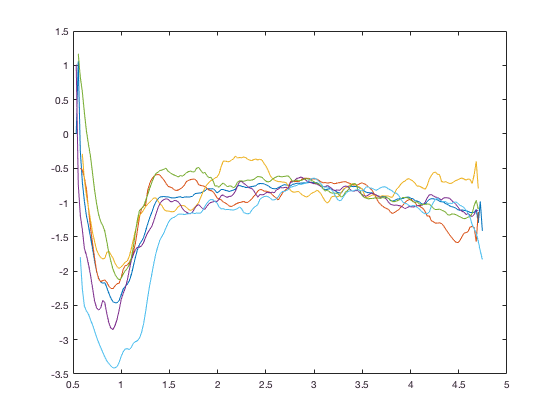

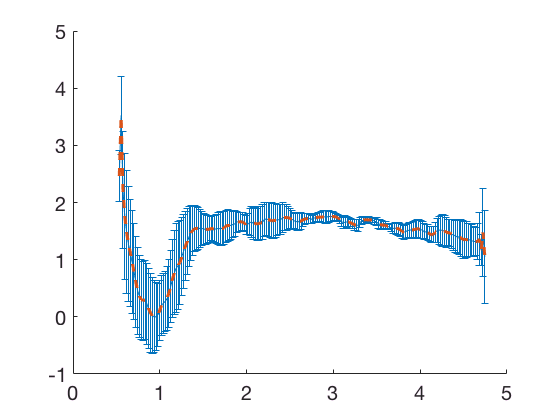

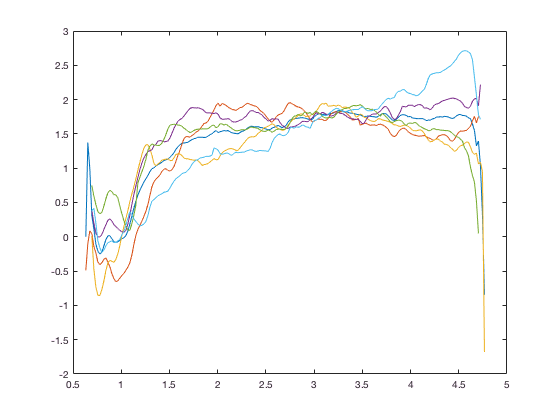

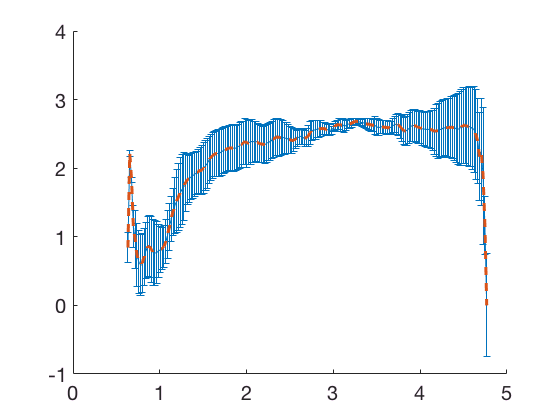

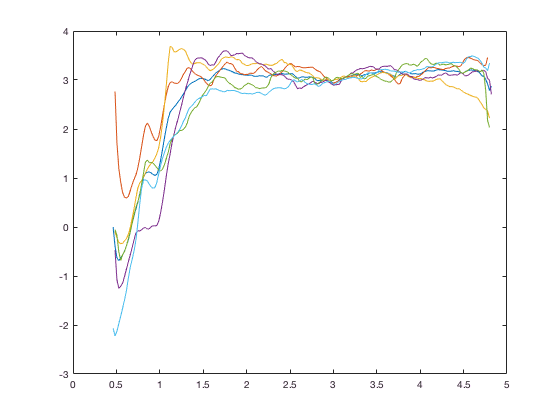

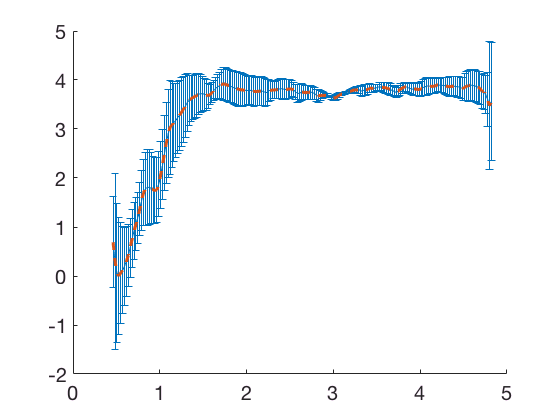

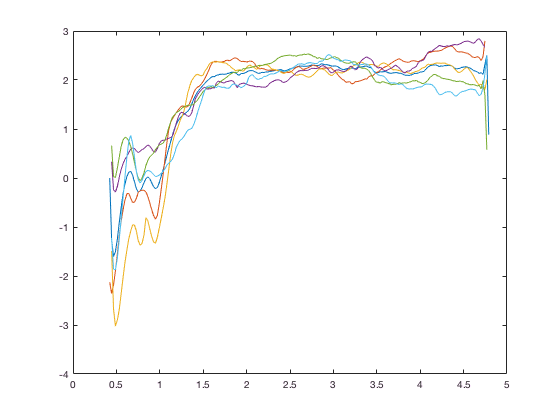

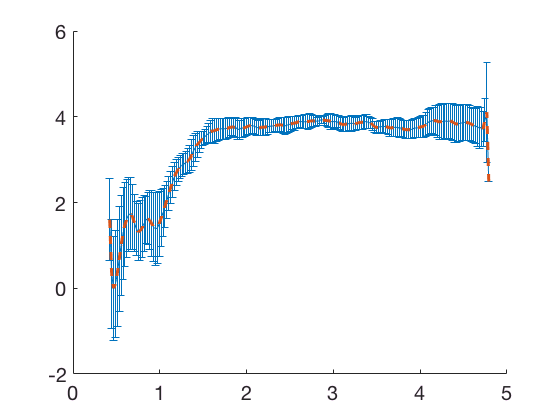

wdirb = '/home/rachael/cluster/scratch/ramansbach/orient_restrain_mon_PMF/arom_line_restrain/eer';
%minmaxxs = zeros(6,2);
minmaxxs = [2.5 4; 2.5 4; 2.5 4; 2.5 4; 2.5 4; 2.5 4];
profEEs = zeros(200,12);
for i = 1:6
tstart = 20000;
tinterval = 6000;
tend = 50000;
remove_entropic = 0;
wdir = [wdirb int2str(i) '/5_umbrella'];
profEE = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,minmaxxs(i,:));
profEEs(:,2*(i-1)+1:2*i) = profEE;
end

profEEmean = mean(profEEs(:,2:2:12),2);

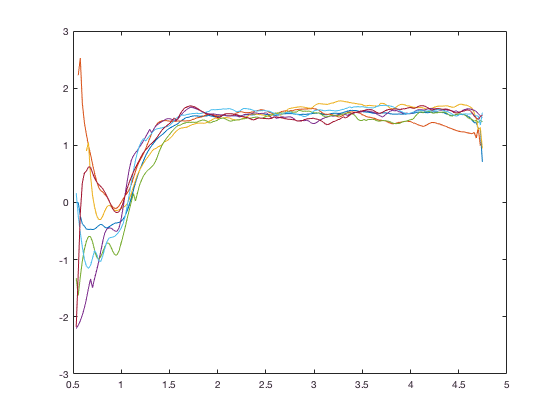

errs = fed_error([profEEs(:,1) profEEmean],profEEs,remove_entropic,[2 3]);

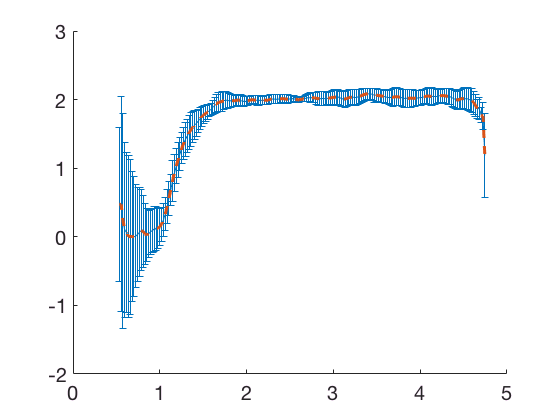

figure()
hold on
set(gca,'fontsize',20)
errorbar(profEEs(:,1),profEEmean-min(profEEmean),errs)
plot(profEEs(:,1),profEEmean-min(profEEmean),'--','linewidth',2)

The sort of double nature of this makes me wonder if we should be doing 2-3 beads for the SC, or is that too much?  I want to see the initial atomistic as well to see if this bimodal nature is reproduced.  It might be something to try?  (Sticky bead followed by unsticky bead followed by another sticky bead?)

**Approximate Morse Fit**

Set the zero of potential to somewhere around where the final potential point is.

Umorse = fittype('Mdeps*((1-exp(-Mrinv*(r-req)))^2-1)','independent','r');
UMfit = fit(profEE(:,1),profEE(:,2)-profEE(end,2),Umorse,'Lower',[0,0,0],'Upper',[10,10,2]);

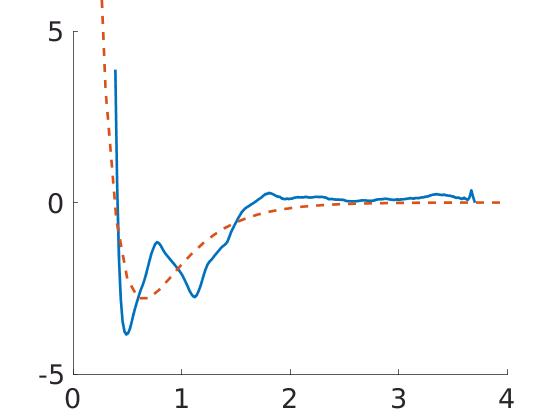

figure()
hold on
ylim([-5 5])
set(gca,'fontsize',20)
plot(profEE(:,1),profEE(:,2)-profEE(end,2),'linewidth',2)
plot(0:0.1:4,UMfit(0:0.1:4),'--','linewidth',2)

fprintf('Approximate morse fit parameters:\n')

Approximate morse fit parameters:


fprintf('Mdeps (Well depth): %f kT\n',UMfit.Mdeps);

Mdeps (Well depth): 2.836959 kT


fprintf('Mrinv (Well width): %f 1/nm\n',UMfit.Mrinv);

Mrinv (Well width): 2.606094 1/nm


fprintf('req (Eq. bond length): %f nm\n',UMfit.req);

req (Eq. bond length): 0.646879 nm


**Isolated Aromatics**

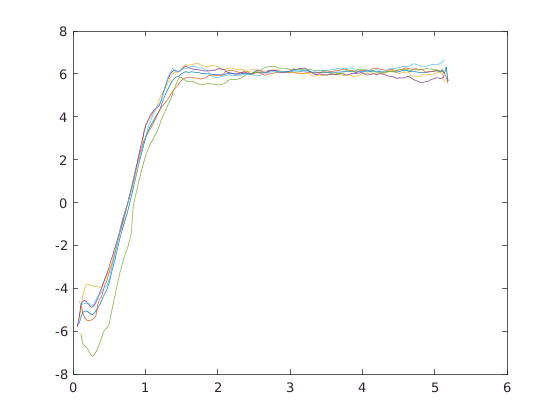

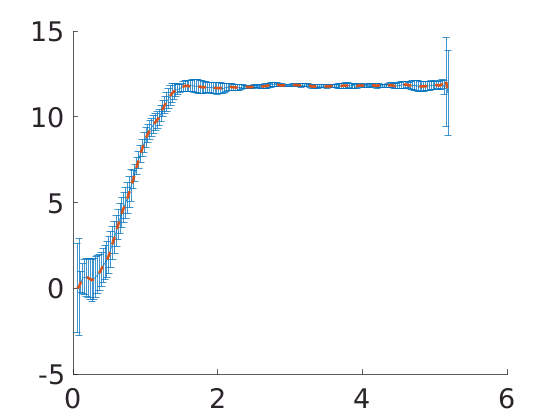

wdir = '/home/rachael/cluster/scratch/ramansbach/orient_restrain_mon_PMF/arom_line_restrain/arom_alone/5_umbrella';
tstart = 50;
tinterval = 5000;
tend = 25050;
remove_entropic = 2;
profIA = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[2 4]);

**Cross Flat**

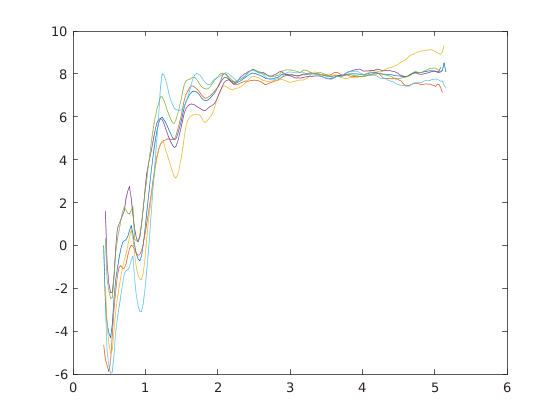

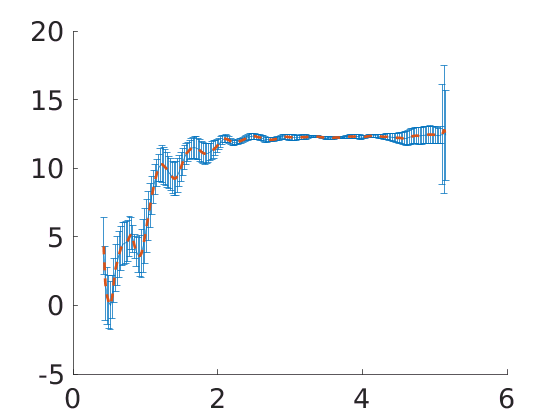

wdir = '/home/rachael/cluster/scratch/ramansbach/orient_restrain_mon_PMF/arom_line_restrain/cross-flat/5_umbrella';
tstart = 5050;
tinterval = 4000;
tend = 25050;
remove_entropic = 0;

profCF = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic);

## Atomistic PMFs

**Pull Non-restrained Atomistic Dimer from Figure to Get Approximate Morse Fit**

Tnn = getDataFromPlot('/home/rachael/coarsegraining/Data/dimerPMFStabbb');
CGx = Tnn(1).XData;
CGy = Tnn(1).YData;
AAx = Tnn(2).XData;
AAy = Tnn(2).YData;